a=1

a = 1

i=3.87

i = 3.8700

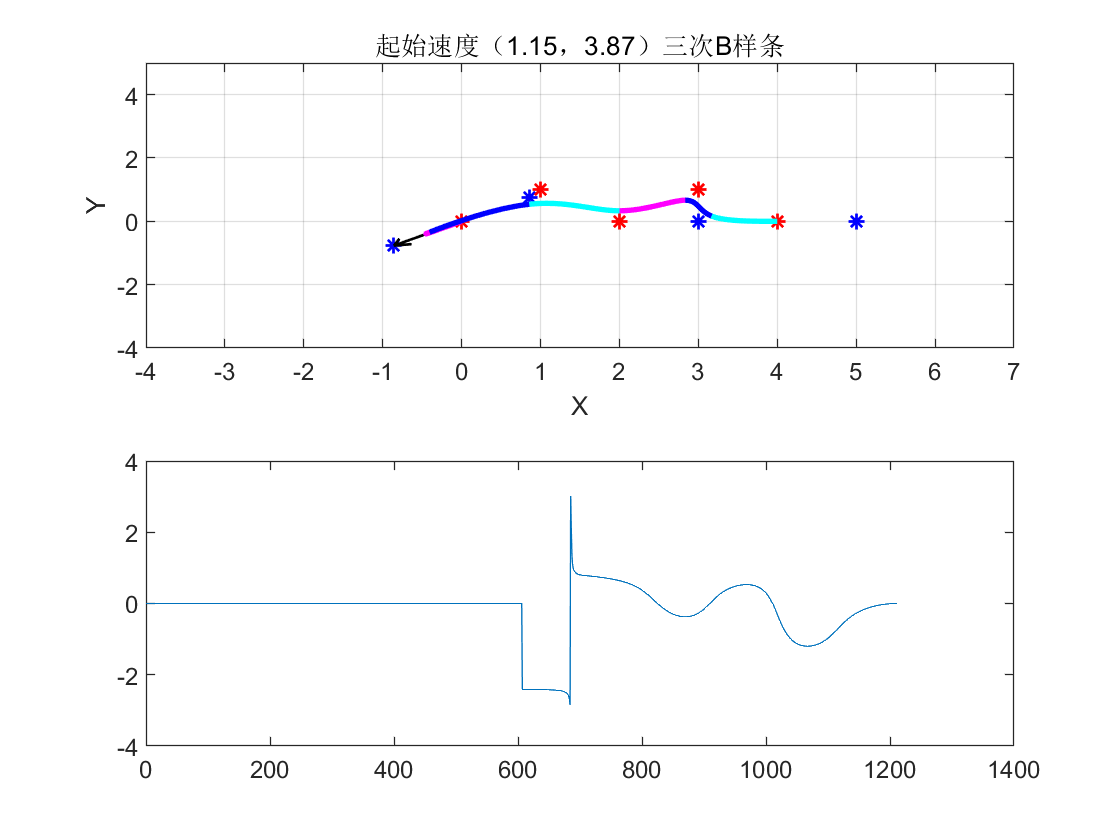


import inc.BsplineSE_ATH;

%% 五控制点B样条曲线
C=[0 1 2 3 4  
   0 1 0 1 0 ];

% 起始点速度
% Aths=[1;pi];
% Athe=[1;0];

% 轮距
L=1;
% 设置窗口位置和大小 [左, 下, 宽, 高]
% figure('Position', [100, 100, 1000, 800]);  % 位置[100,100]，大小800×600


Aths=[a+(i/2*pi*0.025);i];
Athe=[1;0];
subplot(2,1,1);
p=BsplineSE_ATH(C,Aths,Athe,L,sprintf('起始速度（%.2f，%.2f）三次B样条',a+(i/2*pi*0.025),i));

% 计算参数t（通常使用索引或累积弧长）
n = size(p, 2);
t = 1:n;  % 使用索引作为参数

% 计算关于参数t的导数
dx_dt = gradient(p(1,:), t);
dy_dt = gradient(p(2,:), t);
subplot(2,1,2);

% 速度向量（一阶导数）
% velocity = sqrt(dx_dt.^2 + dy_dt.^2);
velocity=atan2(dy_dt,dx_dt);
plot(t,velocity);